rosinit;

Launching ROS Core...
Done in 0.36239 seconds.
Initializing ROS master on http://192.168.0.164:11311.
Initializing global node /matlab_global_node_42874 with NodeURI http://ubuntuStation.Home:38925/ and MasterURI http://localhost:11311.


node = ros2node('/shelfino1/global_costmap/global_costmap');

subscriber = ros2subscriber(node, '/shelfino1/global_costmap/costmap');

msg = receive(subscriber)

msg = struct with fields:
    MessageType: 'nav_msgs/OccupancyGrid'
         header: [1×1 struct]
           info: [1×1 struct]
           data: [23000000×1 int8]


pose_node = ros2node('/shelfino1/amcl');

pose_sub = ros2subscriber(pose_node, '/shelfino1/amcl_pose', "Reliability","reliable", "History","keeplast", "Durability","transientlocal", "Depth",100);

pose = receive(pose_sub);

pose_node_3 = ros2node('/shelfino3/amcl');

pose_sub_3 = ros2subscriber(pose_node, '/shelfino3/amcl_pose', "Reliability","reliable", "History","keeplast", "Durability","transientlocal", "Depth",100);

pose_msg_3 = receive(pose_sub_3);

occupancyGrid = rot90(rot90(reshape(msg.data, msg.info.width, msg.info.height)));

map = binaryOccupancyMap(occupancyGrid);

function rf = rotate(obj)
   rf = rot90(rot90(obj));
end

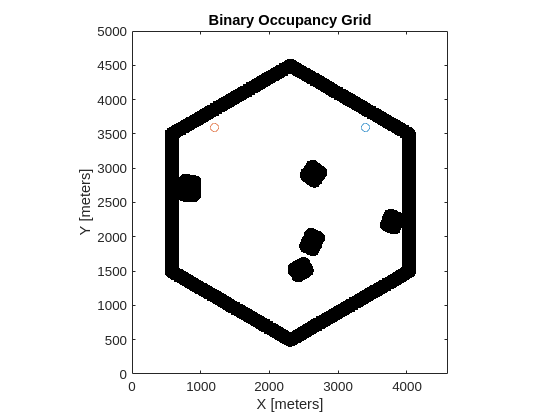

figure
show(map);
hold on 

resolution = msg.info.resolution;
origin = [double(msg.info.width / 2.0), double(msg.info.height/2.0)];
rotation = [0, -1; 1,0];

pose_x = pose.pose.pose.position.x;
pose_y = pose.pose.pose.position.y;

pose_x_3 = pose_msg_3.pose.pose.position.x;
pose_y_3 = pose_msg_3.pose.pose.position.y;

pose_1 = rotate(origin' + [pose_x; pose_y]/resolution);
pose_3 = rotate(origin' + [pose_x_3; pose_y_3]/resolution);



plot(pose_1(1), pose_1(2), "o")
plot(pose_3(1), pose_3(2), "o")
hold off

function [cellMatrix, numCellsX, numCellsY] = fixedCellDecomposition(grid, cellSize)
% FIXEDCELLDECOMPOSITION Decompose a binary occupancy grid into cells of fixed dimension.
%
%   [cellMatrix, numCellsX, numCellsY] = FIXEDCELLDECOMPOSITION(grid, cellSize)
%
%   Inputs:
%       grid     - 2D binary matrix representing the occupancy grid 
%                  (0 = free, 1 = obstacle).
%       cellSize - Scalar integer specifying the dimension for each cell
%                  (square cells of size cellSize x cellSize).
%
%   Outputs:
%       cellMatrix - 2D matrix of size (numCellsY x numCellsX), where each entry
%                    indicates the occupancy status of that cell:
%                      0 = entirely free
%                      1 = partially or fully occupied
%       numCellsX  - Number of cells along the x (column) direction.
%       numCellsY  - Number of cells along the y (row) direction.

    % Validate inputs
    if ~ismatrix(grid) || ~isnumeric(grid)
        error('grid must be a 2D numeric matrix.');
    end
    
    [rows, cols] = size(grid);
    if cellSize < 1 || cellSize > min(rows, cols)
        error('Invalid cellSize. Must be between 1 and min(rows, cols).');
    end
    
    % Compute how many cells fit along each dimension
    numCellsX = ceil(cols / cellSize);
    numCellsY = ceil(rows / cellSize);
    
    % Initialize output matrix
    cellMatrix = zeros(numCellsY, numCellsX, 'uint8');
    
    % Loop over the grid in blocks of cellSize x cellSize
    for cy = 1:numCellsY
        for cx = 1:numCellsX
            % Top-left corner of the current cell (in grid coordinates)
            rowStart = (cy-1)*cellSize + 1;
            colStart = (cx-1)*cellSize + 1;
            
            % Bottom-right corner (clamped to grid boundaries)
            rowEnd = min(rowStart + cellSize - 1, rows);
            colEnd = min(colStart + cellSize - 1, cols);
            
            % Extract the sub-block
            subBlock = grid(rowStart:rowEnd, colStart:colEnd);
            
            % Determine if the cell is free or occupied
            %   Criteria: if there's at least one '1' in subBlock, mark cell as occupied
            if any(subBlock(:) == 1)
                cellMatrix(cy, cx) = 1;
            else
                cellMatrix(cy, cx) = 0;
            end
        end
    end
end

function plotFixedCellDecomposition(grid, cellMatrix, cellSize)
% PLOTFIXEDCELLDECOMPOSITION Plot a binary occupancy grid with fixed-size cell decomposition.
%
%   PLOTFIXEDCELLDECOMPOSITION(grid, cellMatrix, cellSize)
%
%   Inputs:
%       grid       - 2D binary matrix representing the occupancy grid.
%       cellMatrix - 2D matrix (numCellsY x numCellsX) representing the cell decomposition.
%       cellSize   - Scalar integer specifying the dimension of each cell.

    figure('Name','Fixed-Size Cell Decomposition','NumberTitle','off');
    
    % Plot the original grid
    subplot(1,2,1);
    imagesc(grid);
    colormap(gray);
    axis equal tight;
    title('Original Occupancy Grid');
    hold on;
    
    % Plot the cell decomposition
    subplot(1,2,2);
    imagesc(grid);
    colormap(gray);
    axis equal tight;
    title('Cell Decomposition (red outlines)');
    hold on;
    
    [numCellsY, numCellsX] = size(cellMatrix);
    [rows, cols] = size(grid);
    
    % Draw rectangle outlines for each cell
    for cy = 1:numCellsY
        for cx = 1:numCellsX
            % Top-left corner of the current cell
            rowStart = (cy-1)*cellSize + 1;
            colStart = (cx-1)*cellSize + 1;
            
            % Clamp bottom-right corner to grid boundaries
            rowEnd = min(rowStart + cellSize - 1, rows);
            colEnd = min(colStart + cellSize - 1, cols);
            
            % Draw rectangle (image coordinates: x is col, y is row)
            rectangle('Position', [colStart-0.5, rowStart-0.5, colEnd-colStart+1, rowEnd-rowStart+1], ...
                      'EdgeColor', 'r', 'LineWidth', 1);
        end
    end
    hold off;
end

function [cellPath, xyPath] = aStarFixedGrid(cellMatrix, cellSize, startCoord, goalCoord)
% ASTARFIXEDGRID Run A* search on a fixed-cell decomposition of a binary occupancy grid.
%
%   [cellPath, xyPath] = ASTARFIXEDGRID(cellMatrix, cellSize, startCoord, goalCoord)
%
%   Inputs:
%       cellMatrix  - 2D matrix (numCellsY x numCellsX) where 0 = free, 1 = occupied
%       cellSize    - Scalar size of each cell in the original grid
%       startCoord  - [rowStart, colStart] in the original grid
%       goalCoord   - [rowGoal, colGoal] in the original grid
%
%   Outputs:
%       cellPath    - Nx2 list of cell indices (rowCell, colCell) forming the path
%       xyPath      - Nx2 list of approximate (row, col) coordinates in original grid,
%                     corresponding to the center of each cell in cellPath.
%
%   Example:
%       grid = rand(50) < 0.2;            % 50x50 occupancy grid, ~20% obstacles
%       cellSize = 5;
%       [cellMat, nx, ny] = fixedCellDecomposition(grid, cellSize);
%       startCoord = [2, 2];
%       goalCoord  = [40, 44];
%       [cPath, xyP] = aStarFixedGrid(cellMat, cellSize, startCoord, goalCoord);
%       disp(cPath);
%       disp(xyP);

    % 1. Convert start/goal from grid coordinates -> cell indices
    [startCellY, startCellX] = gridToCellIndex(startCoord, cellSize, size(cellMatrix));
    [goalCellY,  goalCellX ] = gridToCellIndex(goalCoord,  cellSize, size(cellMatrix));

    % Check if start or goal is in an occupied cell
    if cellMatrix(startCellY, startCellX) == 1
        error('Start cell is occupied. Cannot proceed.');
    end
    if cellMatrix(goalCellY, goalCellX) == 1
        error('Goal cell is occupied. Cannot proceed.');
    end

    % 2. Run A* on the cell matrix
    cellPath = runAStarOnCells(cellMatrix, [startCellY, startCellX], [goalCellY, goalCellX]);

    % 3. Convert the resulting cell path back to approximate grid coordinates
    xyPath = cellPathToGridCoords(cellPath, cellSize);
end

%% Helper function: Convert from grid [row, col] to cell indices (cellY, cellX)
function [cy, cx] = gridToCellIndex(gridCoord, cellSize, cellMatrixSize)
    % gridCoord = [row, col] in original occupancy grid
    % cellSize  = scalar dimension of each cell
    % cellMatrixSize = [numCellsY, numCellsX]
    
    row = gridCoord(1);
    col = gridCoord(2);

    % Compute cell indices (1-based)
    cx = floor((col - 1) / cellSize) + 1;
    cy = floor((row - 1) / cellSize) + 1;

    % Clamp to valid range
    cy = max(1, min(cy, cellMatrixSize(1)));
    cx = max(1, min(cx, cellMatrixSize(2)));
end

%% Helper function: A* search on the cell matrix
function path = runAStarOnCells(cellMat, startCell, goalCell)
    % cellMat : 0 = free, 1 = occupied
    % startCell = [rowCellStart, colCellStart]
    % goalCell  = [rowCellGoal,  colCellGoal]

    numRows = size(cellMat, 1);
    numCols = size(cellMat, 2);

    % Initialize cost arrays
    gCost = inf(numRows, numCols);
    fCost = inf(numRows, numCols);
    cameFrom = zeros(numRows, numCols, 2); % for storing parent cell (row, col)

    % Start node
    gCost(startCell(1), startCell(2)) = 0;
    fCost(startCell(1), startCell(2)) = heuristicCost(startCell, goalCell);

    % Open set: store cells to explore
    openSet = [startCell(1), startCell(2)];

    % Keep track of visited cells
    closedSet = false(numRows, numCols);

    while ~isempty(openSet)
        % Find cell in openSet with lowest fCost
        currentIdx = lowestFcostIndex(openSet, fCost);
        currentCell = openSet(currentIdx, :);
        cy = currentCell(1);
        cx = currentCell(2);

        % Check if reached goal
        if cy == goalCell(1) && cx == goalCell(2)
            % Reconstruct path
            path = reconstructPath(cameFrom, currentCell);
            return;
        end

        % Remove current from openSet
        openSet(currentIdx, :) = [];
        closedSet(cy, cx) = true;

        % Iterate neighbors (4-direction or 8-direction as desired)
        neighbors = getNeighbors(cy, cx, numRows, numCols);
        for i = 1:size(neighbors,1)
            ny = neighbors(i,1);
            nx = neighbors(i,2);

            % Skip if in closedSet or occupied cell
            if closedSet(ny, nx) || cellMat(ny, nx) > 0
                continue;
            end

            % Tentative cost (assume uniform step cost = 1)
            tentative_g = gCost(cy, cx) + 1;

            % If neighbor not in openSet, add it
            if ~inOpenSet(ny, nx, openSet)
                openSet = [openSet; ny, nx];
            elseif tentative_g >= gCost(ny, nx)
                % Not a better path
                continue;
            end

            % Best path so far
            cameFrom(ny, nx, :) = [cy, cx];
            gCost(ny, nx) = tentative_g;
            fCost(ny, nx) = gCost(ny, nx) + heuristicCost([ny, nx], goalCell);
        end
    end

    % If we exit the loop with no path found
    path = [];
end

%% Helper: Heuristic cost (Manhattan distance) for A*
function h = heuristicCost(cellA, cellB)
    % cellA = [rowA, colA]
    % cellB = [rowB, colB]
    dy = abs(cellA(1) - cellB(1));
    dx = abs(cellA(2) - cellB(2));
    h = dy + dx;  % Manhattan distance
end

%% Helper: Find index of the lowest fCost cell in openSet
function idx = lowestFcostIndex(openSet, fCost)
    % openSet is Nx2 of [row, col]
    % fCost is matrix of the same shape as cellMat
    costs = zeros(size(openSet,1),1);
    for i = 1:size(openSet,1)
        r = openSet(i,1);
        c = openSet(i,2);
        costs(i) = fCost(r,c);
    end
    [~, idx] = min(costs);
end

%% Helper: Check if a neighbor is already in openSet
function tf = inOpenSet(r, c, openSet)
    tf = any(openSet(:,1) == r & openSet(:,2) == c);
end

%% Helper: Return valid neighbors (4-direction) for cell (cy, cx)
function nbrs = getNeighbors(cy, cx, maxY, maxX)
    potential = [
        cy-1, cx;    % up
        cy+1, cx;    % down
        cy,   cx-1;  % left
        cy,   cx+1;  % right
    ];
    % Filter valid
    valid = potential(:,1) >= 1 & potential(:,1) <= maxY & ...
            potential(:,2) >= 1 & potential(:,2) <= maxX;
    nbrs = potential(valid, :);
end

%% Helper: Reconstruct path from 'cameFrom' data
function path = reconstructPath(cameFrom, currentCell)
    % Walk backward until we reach [0,0] parent
    stack = currentCell;
    cy = currentCell(1);
    cx = currentCell(2);

    while ~all(cameFrom(cy, cx, :) == 0)
        parent = squeeze(cameFrom(cy, cx, :))';
        stack = [parent; stack];
        cy = parent(1);
        cx = parent(2);
    end
    path = stack;
end

%% Helper: Convert a path in cell indices to approximate grid coordinates
function xyPath = cellPathToGridCoords(cellPath, cellSize)
    % For each cell [cy, cx], return approximate center in original grid [row, col]
    N = size(cellPath,1);
    xyPath = zeros(N,2);
    for i = 1:N
        cy = cellPath(i,1);
        cx = cellPath(i,2);
        % Center of cell: row ~ (cy-1)*cellSize + cellSize/2
        %                 col ~ (cx-1)*cellSize + cellSize/2
        centerRow = (cy - 1)*cellSize + cellSize/2;
        centerCol = (cx - 1)*cellSize + cellSize/2;
        xyPath(i,:) = [centerRow, centerCol];
    end
end


% 1. Generate a random occupancy grid (binary)
gridSize = 50;

% 2. Decompose the grid into fixed cells
cellSize = 100; % e.g., 5x5 cells
[cellMatrix, numCellsX, numCellsY] = fixedCellDecomposition(occupancyGrid, cellSize);

% Display decomposition info
disp(['Number of cells in X direction: ', num2str(numCellsX)]);

Number of cells in X direction: 46


disp(['Number of cells in Y direction: ', num2str(numCellsY)]);

Number of cells in Y direction: 50


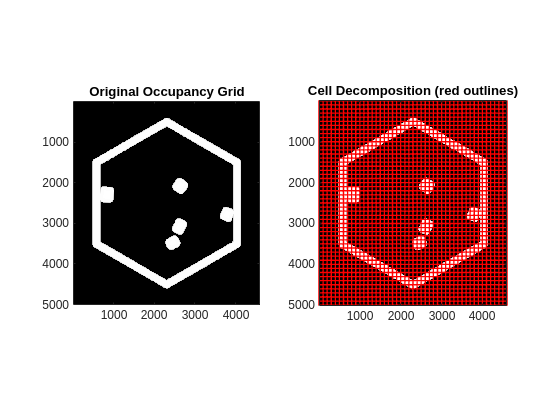

plotFixedCellDecomposition(occupancyGrid, cellMatrix, cellSize);

function testAStarFixedGrid(occupancyGrid, startCoord, goalCoord, rows, cols)

    % 2. Decompose the grid into fixed cells
    cellSize = 100;
    [cellMat, numCellsX, numCellsY] = fixedCellDecomposition(occupancyGrid, cellSize);

    % 4. Run A* on the fixed grid
    [cellPath, xyPath] = aStarFixedGrid(cellMat, cellSize, startCoord, goalCoord);

    % 5. Visualize
    if isempty(cellPath)
        disp('No path found!');
    else
        disp('Cell path (rowCell, colCell):');
        disp(rotate(cellPath));

        disp('Approximate XY path (row, col) in the original grid:');
        disp(rotate(xyPath));

        % Optional: Plot results
        figure('Name','A* on Fixed Cell Decomposition','NumberTitle','off');

        % Original occupancy grid
        subplot(1,2,1);
        imagesc(occupancyGrid);
        colormap(gray);
        axis equal tight;
        title('Occupancy Grid');
        hold on;
        plot(startCoord(2), startCoord(1), 'go', 'MarkerSize', 8, 'LineWidth', 2); % (x=col, y=row)
        plot(goalCoord(2), goalCoord(1), 'ro', 'MarkerSize', 8, 'LineWidth', 2);

        % Decomposition visualization
        subplot(1,2,2);
        imagesc(occupancyGrid);
        colormap(gray);
        axis equal tight;
        title('Fixed Cell + Path');
        hold on;

        % Overlay cell boundaries (optional)
        for cy = 1:numCellsY
            for cx = 1:numCellsX
                rowStart = (cy-1)*cellSize + 1;
                colStart = (cx-1)*cellSize + 1;
                rowEnd   = min(rowStart + cellSize - 1, rows);
                colEnd   = min(colStart + cellSize - 1, cols);
                rectangle('Position',[colStart-0.5, rowStart-0.5, colEnd-colStart+1, rowEnd-rowStart+1],...
                          'EdgeColor','r','LineWidth',0.5);
            end
        end

        % Plot path in original grid coords
        if ~isempty(xyPath)
            plot(xyPath(:,2), xyPath(:,1), 'b-o', 'MarkerSize', 4, 'LineWidth', 1.5);
        end
    end
end

Cell path (rowCell, colCell):
    13    15
    14    15
    15    15
    16    15
    17    15
    18    15
    19    15
    20    15
    21    15
    22    15
    23    15
    24    15
    25    15
    26    15
    27    15
    28    15
    29    15
    30    15
    31    15
    32    15
    33    15
    34    15
    34    16
    34    17
    34    18
    34    19
    34    20
    34    21
    34    22
    34    23
    34    24
    34    25
    34    26
    34    27
    34    28
    34    29
    34    30
    34    31
    34    32
    34    33
    34    34
    34    35
    34    36

Approximate XY path (row, col) in the original grid:
        1250        1450
        1350        1450
        1450        1450
        1550        1450
        1650        1450
        1750        1450
        1850        1450
        1950        1450
        2050        1450
        2150        1450
        2250        1450
        2350        1450
        2450        1450
        2550        1450
       

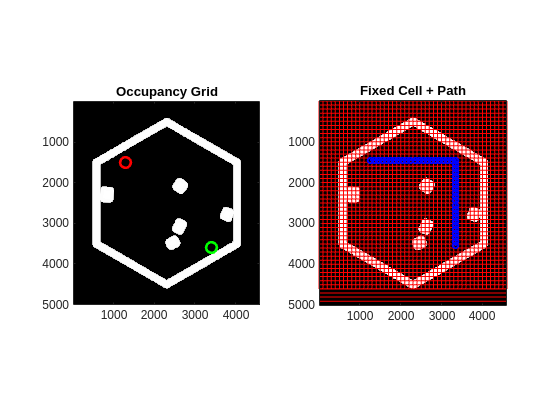

startCoords = rot90(origin' + [pose_x; pose_y]/resolution);
goalCoords = rot90(origin' + [-5; -5]/resolution);

testAStarFixedGrid(occupancyGrid, startCoords, goalCoords, msg.info.height, msg.info.width)

rosshutdown;